## Scattering Test

clc
clear
close all

q = 1.602e-19; % C
h = 6.626e-34; % Joule seconds
h_bar = h / (2*pi); % Joule seconds
KB_J = 1.381e-23; % Boltzmann constant in J/K
T = 300; % room temperature at degrees K
N = 1000; % number of particles
m_e = 9.109e-31; % electron rest mass in kg
m_gamma = 0.067 * m_e; % effective mass of electron in gamma valley
m_X = 0.58 * m_e; % effective mass of electron in X valley
m_L = 0.17 * m_e; % effective mass of electron in L valley
m_eff = [m_gamma m_X m_L];
E_phonon = 35.36e-3 * q; % energy of a phonon in GaAs in J
w_LO = E_phonon / h_bar; % rad/s for phonon in GaAs
e_s = 12.9; % static dielectric constant
e_inf = 10.9; % high-frequency dielectric constant
e_0 = 8.854e-12; % vacuum permittivity in F/m
N_0 = 1 / (exp(E_phonon / (KB_J * T)) - 1); % phonon occupation number
p = 5370; % mass density of GaAs, kg/m^3

**Initial Values**

E_kin = linspace(2, 0, 10000) * q;
Z_if = [0 3 4
        1 2 4
        1 3 3]; % # of final valleys
D_if = [0 10 1.8
        10 10 1
        1.8 1 5] * (q / 1e-10); % from eV / Angstrom to J/m
E_if = [0 .48 .29
       -.48 0 -.19
       -.29 .19 0] * q;
inter_phonon = [0 .0299 .0278
              .0299 .0299 .0293
              .0278 .0293 .029] * q; % intervalley phonon energy in eV
w_if = inter_phonon / h_bar;
D_acoustic = [7.01 9 9.2] * q; % Deformation potential in J for gamma, X, L valley
v_s = 5220; % sound velocity in GaAs in m/s

**Polar-Optical-Phonon Scattering**

function pop_scatter = pop_emit(E, m, h_bar, w_0, E_phonon, KB_J, q, e_inf, e_s, e_0, T)
    pop_scatter = zeros(1, length(E));
    for i = 1:length(E)
        x = h_bar * w_0 / E(i);
        C = ((q^2 * w_0) / (8 * pi * e_0)) * sqrt(2 * m / (h_bar^2)) * ...
            ((1 / e_inf) - (1 / e_s)) * (1 / sqrt(E(i)));
        N_0 = 1 / (exp(E_phonon / (KB_J * T)) - 1);
    
        if E(i) > (h_bar * w_0)
            pop_scatter(i) = C * ((N_0 + 1) * log(abs((1 + sqrt(1 - x)) / (1 - sqrt(1 - x)))));
        end
    end
end

function pop_scatter = pop_abs(E, m, h_bar, w_0, E_phonon, KB_J, q, e_inf, e_s, e_0, T)
    pop_scatter = zeros(1, length(E));
    for i = 1:length(E)
        x = h_bar * w_0 / E(i);
        C = ((q^2 * w_0) / (8 * pi * e_0)) * sqrt(2 * m / (h_bar^2)) * ...
            ((1 / e_inf) - (1 / e_s)) * (1 / sqrt(E(i)));
        N_0 = 1 / (exp(E_phonon / (KB_J * T)) - 1);
    
        pop_scatter(i) = C * (N_0 * log(abs((1 + sqrt(1 + x)) / (-1 + sqrt(1 + x)))));
    end
end

**Acoustic**

function acoustic = ac_scatter(E, m, h_bar, p, v_s, D, KB_J, T)
    acoustic = (D^2 * KB_J * T) / (2 * pi * h_bar * p * v_s^2) * ...
        ((2 * m) / (h_bar ^ 2)) ^ 1.5 * sqrt(E);
end

**Intervalley Scattering**

function gamma_inter_abs = inter_scatter_abs(E, h_bar, KB_J, T, D_if, Z_if, w_if, E_if, m_final, p, E_phonon)
    gamma_inter_abs = zeros(1, length(E));
    for j = 1:length(E)
        N_if = 1 / (exp(h_bar * w_if / (KB_J * T)) - 1);
        g_DOS = DOS(E(j) + E_phonon - E_if, m_final, h_bar);
        gamma_inter_abs(j) = N_if * (pi * D_if^2 * Z_if / (2 * p * w_if)) * g_DOS;
    end
end

function gamma_inter_emit = inter_scatter_emit(E, h_bar, KB_J, T, D_if, Z_if, w_if, E_if, m_final, p, E_phonon)
    gamma_inter_emit = zeros(1, length(E));
    for j = 1:length(E)
        N_if = 1 / (exp(h_bar * w_if / (KB_J * T)) - 1);
        g_DOS = DOS(E(j) - E_phonon - E_if, m_final, h_bar);
        gamma_inter_emit(j) = (N_if + 1) * (pi * D_if^2 * Z_if / (2 * p * w_if)) * g_DOS;
    end
end

**DOS**

function g_DOS = DOS(E, m, h_bar)
    if E > 0
        g_DOS = (sqrt(E) / (2 * (pi^2))) * (2 * m / (h_bar ^ 2)) ^ 1.5;
    else
        g_DOS = 0;
    end
end

**Graphing**

Gamma Scattering

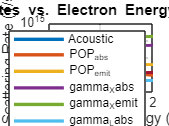

x = 1;
gamma_1 = ac_scatter(E_kin, m_eff(x), h_bar, p, v_s, D_acoustic(x), KB_J, T);
gamma_2 = pop_abs(E_kin, m_eff(x), h_bar, w_LO, E_phonon, KB_J, q, e_inf, e_s, e_0, T);
gamma_3 = pop_emit(E_kin, m_eff(x), h_bar, w_LO, E_phonon, KB_J, q, e_inf, e_s, e_0, T);
% Gamma --> X
y = 2;
gamma_4 = inter_scatter_abs(E_kin, h_bar, KB_J, T, D_if(x, y), Z_if(x, y), w_if(x, y), E_if(x, y), m_eff(y), p, inter_phonon(x, y));
gamma_5 = inter_scatter_emit(E_kin, h_bar, KB_J, T, D_if(x, y), Z_if(x, y), w_if(x, y), E_if(x, y), m_eff(y), p, inter_phonon(x, y));
% Gamma --> L
y = 3;
gamma_6 = inter_scatter_abs(E_kin, h_bar, KB_J, T, D_if(x, y), Z_if(x, y), w_if(x, y), E_if(x, y), m_eff(y), p, inter_phonon(x, y));
gamma_7 = inter_scatter_emit(E_kin, h_bar, KB_J, T, D_if(x, y), Z_if(x, y), w_if(x, y), E_if(x, y), m_eff(y), p, inter_phonon(x, y));

% Plot the scattering rates
figure;
semilogy(E_kin / q, gamma_1, 'LineWidth', 2);
hold on;
semilogy(E_kin / q, gamma_2, 'LineWidth', 2);
semilogy(E_kin / q, gamma_3, 'LineWidth', 2);
semilogy(E_kin / q, gamma_4, 'LineWidth', 2);
semilogy(E_kin / q, gamma_5, 'LineWidth', 2);
semilogy(E_kin / q, gamma_6, 'LineWidth', 2);
semilogy(E_kin / q, gamma_7, 'LineWidth', 2);
hold off;

xlabel('Electron Kinetic Energy (eV)');
ylabel('Scattering Rate (1/s)');
title('Scattering Rates vs. Electron Energy (GaAs, \Gamma valley)');
legend('Acoustic', 'POP_{abs}', 'POP_{emit}', 'gamma_X{abs}', 'gamma_X{emit}', 'gamma_L{abs}', 'gamma_L{emit}');
ylim([1e11 1e15]);
grid on;

X Scattering

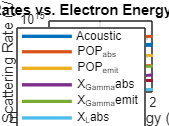

x = 2;
X_1 = ac_scatter(E_kin, m_eff(x), h_bar, p, v_s, D_acoustic(x), KB_J, T);
X_2 = pop_abs(E_kin, m_eff(x), h_bar, w_LO, E_phonon, KB_J, q, e_inf, e_s, e_0, T);
X_3 = pop_emit(E_kin, m_eff(x), h_bar, w_LO, E_phonon, KB_J, q, e_inf, e_s, e_0, T);
% X --> Gamma
y = 1;
X_4 = inter_scatter_abs(E_kin, h_bar, KB_J, T, D_if(x, y), Z_if(x, y), w_if(x, y), E_if(x, y), m_eff(y), p, inter_phonon(x, y));
X_5 = inter_scatter_emit(E_kin, h_bar, KB_J, T, D_if(x, y), Z_if(x, y), w_if(x, y), E_if(x, y), m_eff(y), p, inter_phonon(x, y));
% X --> L
y = 3;
X_6 = inter_scatter_abs(E_kin, h_bar, KB_J, T, D_if(x, y), Z_if(x, y), w_if(x, y), E_if(x, y), m_eff(y), p, inter_phonon(x, y));
X_7 = inter_scatter_emit(E_kin, h_bar, KB_J, T, D_if(x, y), Z_if(x, y), w_if(x, y), E_if(x, y), m_eff(y), p, inter_phonon(x, y));
% X --> X
y = 2;
X_8 = inter_scatter_abs(E_kin, h_bar, KB_J, T, D_if(x, y), Z_if(x, y), w_if(x, y), E_if(x, y), m_eff(y), p, inter_phonon(x, y));
X_9 = inter_scatter_emit(E_kin, h_bar, KB_J, T, D_if(x, y), Z_if(x, y), w_if(x, y), E_if(x, y), m_eff(y), p, inter_phonon(x, y));

% Plot the scattering rates
figure;
semilogy(E_kin / q, X_1, 'LineWidth', 2);
hold on;
semilogy(E_kin / q, X_2, 'LineWidth', 2);
semilogy(E_kin / q, X_3, 'LineWidth', 2);
semilogy(E_kin / q, X_4, 'LineWidth', 2);
semilogy(E_kin / q, X_5, 'LineWidth', 2);
semilogy(E_kin / q, X_6, 'LineWidth', 2);
semilogy(E_kin / q, X_7, 'LineWidth', 2);
semilogy(E_kin / q, X_8, 'LineWidth', 2);
semilogy(E_kin / q, X_9, 'LineWidth', 2);
hold off;

xlabel('Electron Kinetic Energy (eV)');
ylabel('Scattering Rate (1/s)');
title('Scattering Rates vs. Electron Energy (GaAs, X valley)');
legend('Acoustic', 'POP_{abs}', 'POP_{emit}', 'X_{Gamma}{abs}', ...
    'X_{Gamma}{emit}', 'X_L{abs}', 'X_L{emit}', 'X_X{abs}', 'X_X{emit}');
ylim([1e11 1e15]);
grid on;

L Scattering

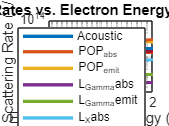

x = 3;
L_1 = ac_scatter(E_kin, m_eff(x), h_bar, p, v_s, D_acoustic(x), KB_J, T);
L_2 = pop_abs(E_kin, m_eff(x), h_bar, w_LO, E_phonon, KB_J, q, e_inf, e_s, e_0, T);
L_3 = pop_emit(E_kin, m_eff(x), h_bar, w_LO, E_phonon, KB_J, q, e_inf, e_s, e_0, T);
% L --> Gamma
y = 1;
L_4 = inter_scatter_abs(E_kin, h_bar, KB_J, T, D_if(x, y), Z_if(x, y), w_if(x, y), E_if(x, y), m_eff(y), p, inter_phonon(x, y));
L_5 = inter_scatter_emit(E_kin, h_bar, KB_J, T, D_if(x, y), Z_if(x, y), w_if(x, y), E_if(x, y), m_eff(y), p, inter_phonon(x, y));
% L --> X
y = 2;
L_6 = inter_scatter_abs(E_kin, h_bar, KB_J, T, D_if(x, y), Z_if(x, y), w_if(x, y), E_if(x, y), m_eff(y), p, inter_phonon(x, y));
L_7 = inter_scatter_emit(E_kin, h_bar, KB_J, T, D_if(x, y), Z_if(x, y), w_if(x, y), E_if(x, y), m_eff(y), p, inter_phonon(x, y));
% L --> L
y = 3;
L_8 = inter_scatter_abs(E_kin, h_bar, KB_J, T, D_if(x, y), Z_if(x, y), w_if(x, y), E_if(x, y), m_eff(y), p, inter_phonon(x, y));
L_9 = inter_scatter_emit(E_kin, h_bar, KB_J, T, D_if(x, y), Z_if(x, y), w_if(x, y), E_if(x, y), m_eff(y), p, inter_phonon(x, y));

% Plot the scattering rates
figure;
semilogy(E_kin / q, L_1, 'LineWidth', 2);
hold on;
semilogy(E_kin / q, L_2, 'LineWidth', 2);
semilogy(E_kin / q, L_3, 'LineWidth', 2);
semilogy(E_kin / q, L_4, 'LineWidth', 2);
semilogy(E_kin / q, L_5, 'LineWidth', 2);
semilogy(E_kin / q, L_6, 'LineWidth', 2);
semilogy(E_kin / q, L_7, 'LineWidth', 2);
semilogy(E_kin / q, L_8, 'LineWidth', 2);
semilogy(E_kin / q, L_9, 'LineWidth', 2);
hold off;

xlabel('Electron Kinetic Energy (eV)');
ylabel('Scattering Rate (1/s)');
title('Scattering Rates vs. Electron Energy (GaAs, L valley)');
legend('Acoustic', 'POP_{abs}', 'POP_{emit}', 'L_{Gamma}{abs}', ...
    'L_{Gamma}{emit}', 'L_X{abs}', 'L_X{emit}', 'L_L{abs}', 'L_L{emit}');
ylim([1e10 1e14]);
grid on;